### 6. Ανίχνευση Ακμών - Κατάτμηση 

Αφού φορτώσουμε την εικόνα και την μετατατρέψουμε απο rgb κανάλια σε gray προκαλώ θόλωμα με gaussian θόρυβο ώστε να απαλλαγώ από τις υψηλές συχνότητες. Διατηρούνται οι ακμές. και χρησιμοποιώ δύο διαφορετικές μάσκες την Sobel και την Prewitt όπου οι πίνακες τιμών τους παρουσιάζονται παρακάτω.

clc;
clear all;
x= imread('images\6\factory.jpg');
x=rgb2gray(x);
%use gaussian filter ----> gaussian blur to get rιd of the high frequency 
% einai edge preserving an to programmatisw mporw na kanw enan pinaka
% gauss=[1 2 1 ; 2 4 2 ; 1 2 1 ] emfash sto kentro kai to kanw convolution
% sthn eikona x
x_blur=imgaussfilt(x);
%sober edge detection
temp=zeros(3,3);

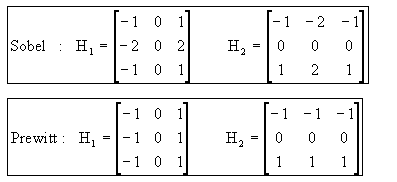

Υλοποιώντας τους κώδικες εφαρμόζουμε τις μάσκες κάθε φορά στην αρχική εικόνα και προκύπτειένας καινόυριος πίνακας κάθε φορά ίδιων διαστάσεων με την αρχική εικόνα x. Η μάσκα Gx  υπολογίζει την παράγωγο στον οριζόντιο άξονα δηλαδή το μέτρο της θα δείχνει απότομες αλλαγές στον άξονα x επομένως η μάσκα αυτή θα ανιχνεύει κατακόρυφες ακμές.Ενώ η μάσκα Gy θα ανιχνεύει τις οριζόντιες ακμές. 

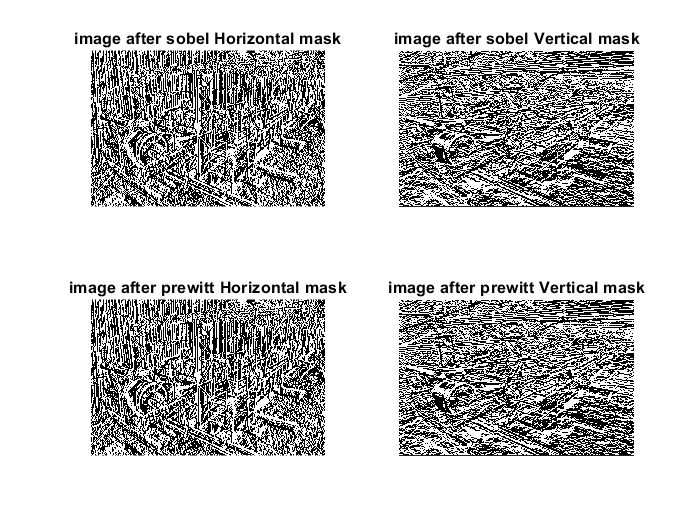

Gx=[-1 0 1; -2 0 2; -1 0 1];
x_augmented=zeros(size(x_blur)+2);
x_augmented(2:421,2:631)=x_blur;
x_sobel_x=[];
for i=1:420
    for j=1:630
        temp=x_augmented(i:i+2,j:j+2).*Gx;
        x_sobel_x(i,j)=sum(temp,'all');
    end
end


Gy=[-1 -2 -1 ; 0 0 0; 1 2 1];
x_sobel_y=[];
for i=1:420
    for j=1:630
        temp=x_augmented(i:i+2,j:j+2).*Gy;
        x_sobel_y(i,j)=sum(temp,'all');
    end
end


Hx=[-1 0 1; -1 0 1; -1 0 1];
Hy=[-1 -1 -1; 0 0 0; 1 1 1];
x_prewitt_x=[];
x_prewitt_y=[];
for i=1:420
    for j=1:630
        temp=x_augmented(i:i+2,j:j+2).*Hx;
        x_prewitt_x(i,j)=sum(temp,'all');
    end
end


for i=1:420
    for j=1:630
        temp=x_augmented(i:i+2,j:j+2).*Hy;
        x_prewitt_y(i,j)=sum(temp,'all');
    end
end
subplot(2,2,1)
imshow(x_sobel_x)
title("image after sobel Horizontal mask")
subplot(2,2,2)
imshow(x_sobel_y)
title("image after sobel Vertical mask")
subplot(2,2,3)
imshow(x_prewitt_x)
title("image after prewitt Horizontal mask")
subplot(2,2,4)
imshow(x_prewitt_y)
title("image after prewitt Vertical mask")

η εικόνα που παριστάνει το μέτρο του διανύσματος αναπαριστά τις συνολικές ακμές (οριζόντιες και κάθετες). 

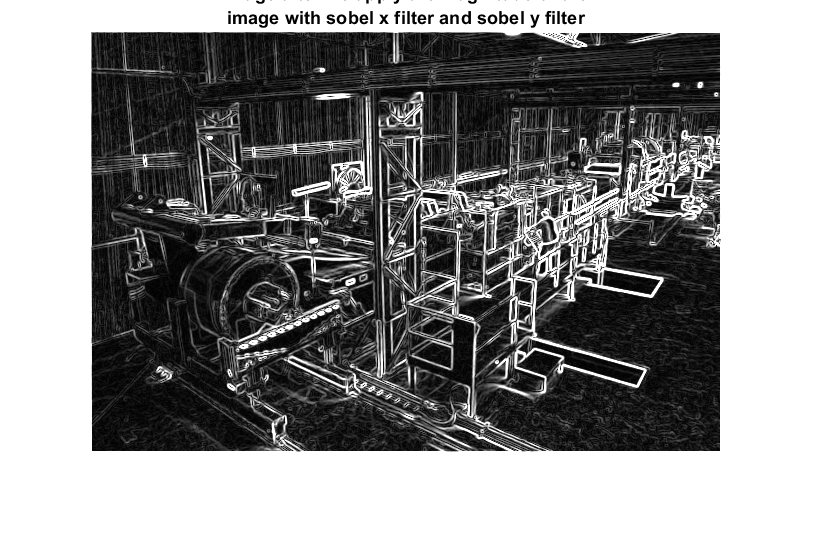

figure()
Magnitude=sqrt(x_sobel_x.^2+x_sobel_y.^2); 
imshow(uint8(Magnitude))
title({'image after we apply the magnitude of the';'image with sobel x filter and sobel y filter'})

2) Πραγματοποιείται ολική κατωφλίωση και χρησιμοποιείται ως τιμή κατωφλιού κάθε φορα το mean value (θα μπορούσε και το median )του κάθε πίνακα ώστε να γίνει μία χοντρική εκτίμηση για την τιμή του threshold.

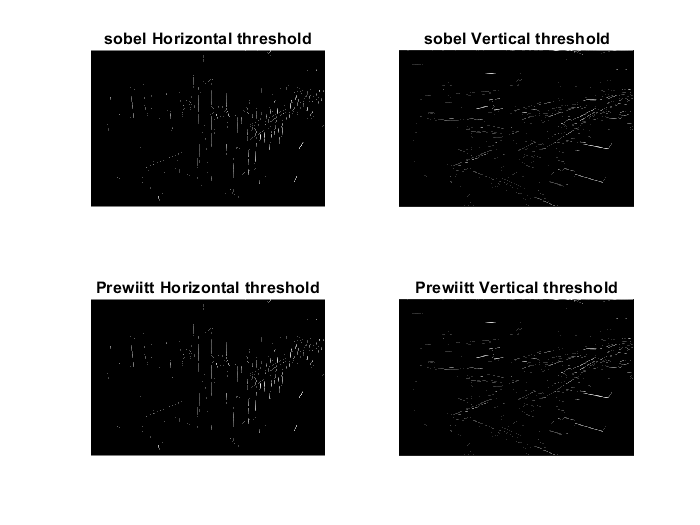

threshold1=mean(x_sobel_x,'all')*255;
threshold2=mean(x_sobel_y,'all')*255;
threshold3=mean(x_prewitt_x,'all')*255;
threshold4=mean(x_prewitt_y,'all')*255;

x_sobel_x_thres=thresholding(x_sobel_x,threshold1);
x_sobel_y_thres=thresholding(x_sobel_y,threshold2);
x_prewitt_x_thres=thresholding(x_prewitt_x,threshold3);
x_prewitt_y_thres=thresholding(x_prewitt_y,threshold4);

figure()
subplot(2,2,1);
imshow(x_sobel_x_thres,[]);
title(sprintf("sobel Horizontal threshold") )

subplot(2,2,2);
imshow(x_sobel_y_thres,[]);
title(sprintf("sobel Vertical threshold") )

subplot(2,2,3);
imshow(x_prewitt_x_thres,[]);
title(sprintf("Prewiitt Horizontal threshold") )

subplot(2,2,4);
imshow(x_prewitt_y_thres,[]);
title(sprintf("Prewiitt Vertical threshold") )

3) Hough Transform

κάθε ευθεία δίνεται απο την εξίσωση xcos(θ) +ysin(θ) = ρ όπου x  και y γνωστά και θ να παίρνει τιμές απο 1,2,...180 και λέπω τι τιμη παίρνω για το ρ κάθε φορά. Χρησιμοποιήθηκε η έτοιμη συνάρτηση σε περιβάλλον matlab hough() .

source : mathworks

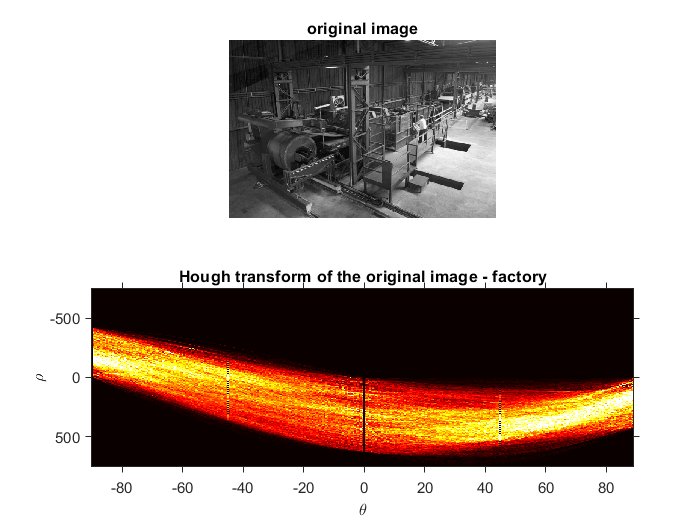

figure()
BW = edge(x,'canny');
[H,T,R] = hough(BW,'RhoResolution',0.5,'Theta',-90:0.5:89);
subplot(2,1,1);
imshow(x);
title('original image');
subplot(2,1,2);
imshow(imadjust(rescale(H)),'XData',T,'YData',R,'InitialMagnification','fit');
title('Hough transform of the original image - factory');
xlabel('\theta'), ylabel('\rho');
axis on, axis normal, hold on;
colormap(gca,hot);

function value =thresholding(I,threshold)
     value=zeros(size(I));
    
     for i=1:size(I,1)-2
        for j=1:size(I,2)-2
            if I(i,j)>threshold
                value(i,j)=I(i,j);
            end
        end
     end
 end
